%Example 3.1 Dorf

A= [0.0,1.0;
    -2.0,1.0];
B= [0.0;
    1.0] ;
Q= [2.0,3.0;
    3.0,5.0];
F=[1.0,0.5;
    0.5,2.0];
R= 0.25;
E = B*inv(R)*B';

[n,m]=size(A);
[nb,mb]=size(B);
[nq,mq] =size (Q) ;
[nr,mr]=size(R);
[nf ,mf] =size (F) ;

% Delta
Delta = [A, -E; -Q, -A'];

% Gamma
Gamma = [zeros(n) eye(n);
         eye(n) zeros(n)];
% Eigen
[W, D] = eig(Delta);

% Organizamo los autovalores
% de menor a mayor
j=n;
[m1,index1]=sort(real(diag(D)));
for i=1:1:n
    m2(i)=m1(j);
    index2(i)=index1(j);
    index2(i+n)=index1(i+n);
    j=j-1;
end

Md=-diag(m2);

for i=1:2*n
    w2(:,i)=W(:,index2(i));
end
W=w2;

W11=zeros(n);
W12=zeros(n);
W21=zeros(n);
W22=zeros(n);
j=1 ;

for i=1:2*n:(2*n*n-2*n+1)
    W11(j:j+n-1)=W(i:i+n-1);
    W21(j:j+n-1)=W(i+n:i+2*n-1);
    W12(j:j+n-1)=W(2*n*n+i:2*n*n+i+n-1);
    W22(j:j+n-1)=W(2*n*n+i+n:2*n*n+i+2*n-1);
    j=j+n;
end

% T(tf)
T_tf = -inv(W22-F*W12)*(W21 - F*W11);


tf = 5;
dt= 0.01;
time = 0.0:dt:tf; 

P = zeros(length(1:0.1:tf),n*n);
i = 1;
for t = time
    Pt = (W21+W22*expm(-Md*(tf-t))*T_tf*...
        expm(-Md*(tf-t)))*inv(W11+W12*expm(-Md*(tf-t))*...
        T_tf*expm(-Md*(tf-t)));
    P(i,:) = reshape(Pt,[1,n*n]);
    i = i +1;
end


% Function
ft = @(t,x,u) A*x + B*u;

%Runge-Kutta 4
k1 = @(t,x,u) (  ft(t,x,u) );
k2 = @(t,x,u) ( ft(t,x + k1(t,x,u)*dt/2,u) );
k3 = @(t,x,u) ( ft(t,x + k2(t,x,u)*dt/2,u) );
k4 = @(t,x,u) ( ft(t,x + k1(t,x,u)*dt,u) );
f_ud = @(t,x,u) ( x + (dt/6) * ( k1(t,x,u) + 2*k2(t,x,u) + 2*k3(t,x,u) + k4(t,x,u)  )   );

x0 =[2;-3];
xOL = zeros(n,length(time));
xOL(:,1) = x0;
xCL = zeros(n,length(time));
xCL(:,1) = x0; 
for i = 1:length(time)-1
    xOL(:,i+1) = f_ud(0,xOL(:,i),0);  %open loop
    u = -(R\B')*reshape(P(i,:),n,n)*xCL(:,i);  % u=
    xCL(:,i+1) = f_ud(0,xCL(:,i),u);
end

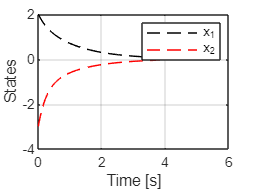

figure(1);
plot(time,xCL(1,:),"--k", "DisplayName","x_1")
hold on;
plot(time,xCL(2,:),"--r", "DisplayName","x_2")
legend
xlabel("Time [s]")
ylabel("States")
grid on;
hold off

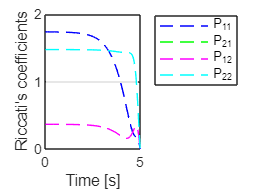

figure(2);
plot(time,P(:,1),"--b", "DisplayName","P_{11}")
hold on;
plot(time,P(:,2),"--g", "DisplayName","P_{21}")
plot(time,P(:,3),"--m", "DisplayName","P_{12}")
plot(time,P(:,4),"--c", "DisplayName","P_{22}")
legend("Location", "bestoutside")
xlabel("Time [s]")
ylabel("Riccati's coefficients")
grid on;